# Panda APF Secondary

clear

## Grid

grid = OctoGrid(2,2,2,100);

% add column
grid.addBox(1.25,0.9,0,0.2,0.2,1.5)

% add wall
grid.addBox(0.6,0.8,0,0.8,0.1,1.5)

## Generate a list of transformations

transformations_list = getPartialTransformationsListPanda('points_per_segment', 5*[1 1 1 1 1 1 1])

transformations_list = 1×35 struct array with fields:
    tree
    segm_num
    segm_part


## Generate goal points

% trajectory generation points (xyz position, xyz angles)
control_points = [1.088 1 0.926 0 0 0;
                  1.4 1.2 0.5 0 0 0]; 

## Calculate field

% Attractive
[grid_attractive] = attractive_field_3D(grid.grid, control_points(2,1:3), grid.resolution);

% Repulsive
kernel_size = 50; % how far should obstacles exert effect
sigma = 25 ; % how quickly should effect exerted by obstacles fall

[grid_repulsive] = convolution_offline_3D(grid.grid,kernel_size,sigma);

% Total
Ka = 10; % attractive field coefficient
Kr = -5; % repulsive field coefficient

% total field is a weighted sum of both
grid_total_field = Ka * grid_attractive + Kr * grid_repulsive;

## Calculate APF Value in i-th point

% robot joints configuration
joints = [0.1520
   -0.3747
    0.2588
   -2.2680
    0.0899
    1.8967
    0.3447];

% robot base transformation (move to x - 1m, y - 1m)
Tbase = eye(4);
Tbase(1:2,4) = [1 1]';

% calculate APF value and get T matrix
[value, transform] = getPartialAPFValueRobotTreePoint(grid_total_field, grid.resolution, transformations_list(1).tree, Tbase, joints)

value = 5.4135

transform =     0.9885   -0.0000   -0.1514    1.0000
    0.1514    0.0000    0.9885    1.0000
         0   -1.0000    0.0000    0.0666
         0         0         0    1.0000


## Draw Robot 

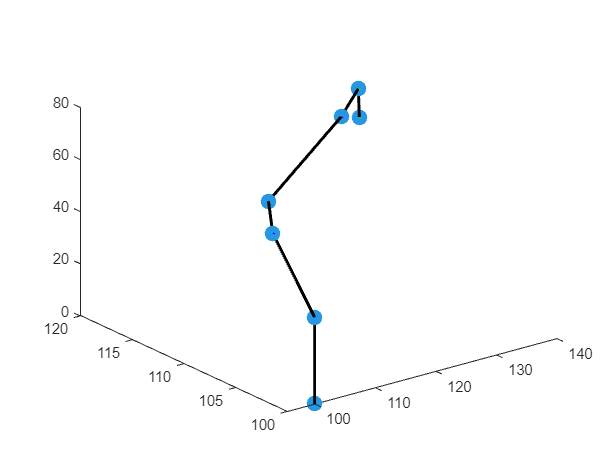

% calculate robot poses for display
[robot_transforms] = GeometricPandaMATLAB(joints, Tbase);

% % display grid
% grid.showGridVol3D(grid.grid,'floor',false,'height',false)
% hold on
% axis equal

% display robot
showPanda(robot_transforms,grid.resolution)
hold off

## Calculate APF Values for all points

APF_interpolated_values = []; % [value x y z]

for i = 1:1:length(transformations_list) % for every detection point

    % calculate APF value and get T matrix
    [value, transform] = getPartialAPFValueRobotTreePoint(grid_total_field, grid.resolution, transformations_list(i).tree, Tbase, joints);

    % save to list
    APF_interpolated_values = [APF_interpolated_values ; value, transform(1:3,4)'];

end

## The point on robot with max APF value

% find max APF value
[val,ind] = max(APF_interpolated_values(:,1))

val = 5.4135

ind = 1

The point with max APF is actually not the closest to the obstacle column, because those are closer to the goal and therfore attractive field compensates (subtracts) the repuslive field.

## Calculate Repulsive only APF Values for all points

APF_Repulsive_interpolated_values = []; % [value x y z]

for i = 1:1:length(transformations_list) % for every detection point

    % calculate APF value and get T matrix
    [value, transform] = getPartialAPFValueRobotTreePoint(grid_repulsive, grid.resolution, transformations_list(i).tree, Tbase, joints);

    % save to list
    APF_Repulsive_interpolated_values = [APF_Repulsive_interpolated_values ; value, transform(1:3,4)'];

end

## The point on robot with max Repulsive APF value

% find max APF value
[val,ind] = max(APF_Repulsive_interpolated_values(:,1))

val = 0.2269

ind = 20

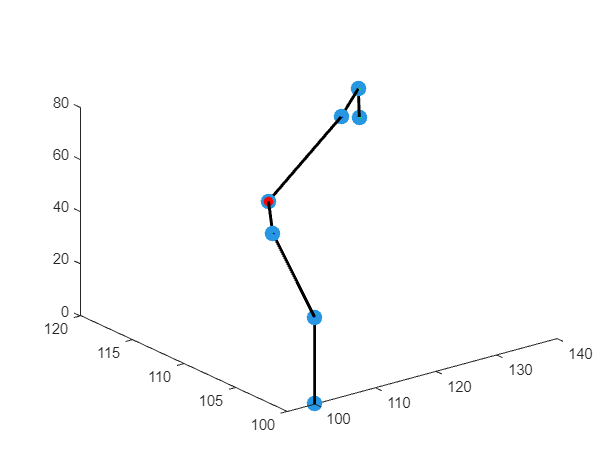

% mark the point with red dot
hold on 
scatter3(APF_Repulsive_interpolated_values(ind,2)*grid.resolution,APF_Repulsive_interpolated_values(ind,3)*grid.resolution,APF_Repulsive_interpolated_values(ind,4)*grid.resolution, 'filled', 'MarkerFaceColor', 'red', 'MarkerEdgeColor', 'red')

## Calculate Repulsive APF Gradient Value in all points

APF_Repulsive_gradient_values = []; % [dx dy dz x y z]

% for every point of detection
for i = 1:1:length(APF_Repulsive_interpolated_values)

    % calculated interpolated derivative of the field
    [dx,dy,dz] = interpolate_derivative(APF_Repulsive_interpolated_values(i,2:4), grid_repulsive, grid.resolution);

    APF_Repulsive_gradient_values = [APF_Repulsive_gradient_values ; dx dy dz APF_Repulsive_interpolated_values(i,2:4)];

end

## Draw APF Gradient Arrows

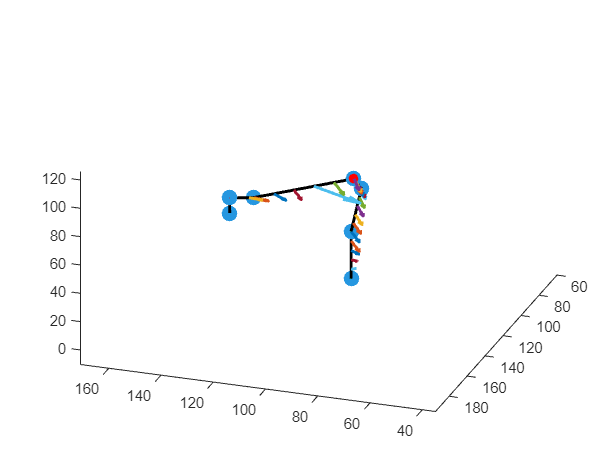

arrow_length = 50; % adjust the length to your preference

for i = 1:1:length(APF_Repulsive_interpolated_values)
    % plot the arrow
    quiver3(APF_Repulsive_gradient_values(i,4)*grid.resolution, APF_Repulsive_gradient_values(i,5)*grid.resolution, APF_Repulsive_gradient_values(i,6)*grid.resolution, APF_Repulsive_gradient_values(i,1) * arrow_length, APF_Repulsive_gradient_values(i,2) * arrow_length, APF_Repulsive_gradient_values(i,3) * arrow_length, arrow_length/2, 'LineWidth', 2, 'MaxHeadSize', 1);
end
% set view
xlim([35 171])
ylim([59 195])
zlim([-10 126])
view([-161 37])

## Calculate trajectory

[joints_positions_APF, EE_positions_APF, goal_distances_APF, q_velocities_APF, ee_velocities_APF, values_APF] = APF_trajectory_closestPoint(grid_total_field, grid_repulsive, grid.resolution, control_points(2,1:3), Tbase, zeros(7,1),'avoid_task',true);

## Draw trajectory

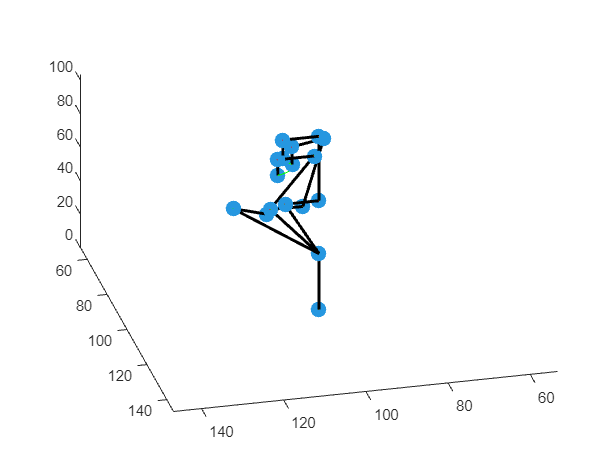

figure

% grid
% grid.showGridVol3D(grid.grid,'floor',false,'height',false)
% hold on
% axis equal

% calculated EE trajectory
plot3(EE_positions_APF(1,:)*grid.resolution,EE_positions_APF(2,:)*grid.resolution,EE_positions_APF(3,:)*grid.resolution,'green')

% draw initial pose
[robot_transforms] = GeometricPandaMATLAB(joints_positions_APF(:,1), Tbase);
showPanda(robot_transforms,grid.resolution)

% draw mid pose
[robot_transforms] = GeometricPandaMATLAB(joints_positions_APF(:,250), Tbase);
showPanda(robot_transforms,grid.resolution)

% draw finish pose
[robot_transforms] = GeometricPandaMATLAB(joints_positions_APF(:,end), Tbase);
showPanda(robot_transforms,grid.resolution)
xlim([53.3 146.7])
ylim([53.3 146.7])
% zlim([53.3 146.7])
view([-90.9 90.0])